# Extra Credit Assignment

**By Tony Kabilan Okeke**

Model the two synaptic currents from Reading 1 in MATLAB (ISG and ISC):

- Re-read this section in the paper methods

-         And make a plan for what your code needs to do2

- Define all constants (keep  in ms and mV)

-         Assume you are in voltage clamp so Vpost stays constant

-         Set Vpost to -60mV

-         Set gs (gmax) to 1 (to make things easier)

-         Set all other parameters as defined in the paper

- Make a time vector 

-         in ms – from 1 to 2000 ms with 1 ms increments

- Make a presynaptic membrane vector (incorporate spikes)

-         Assume Vpre is either resting at -60mV or spiking at -30mV

-         Use the matlab function “randi” to make a vector of random numbers that range from 1 to 100.  The length of this vector needs to be equal to the length of the time vector.

-         Use this random number vector to determine when in time the neuron will spike. Assume the neuron spikes when a random number = 100 but otherwise is at rest – using this info, use your random number vector to generate the membrane potential for the presynaptic neuron **[plot]**

- Calculate sbar **[plot]** and tau

- Use a numerical method to calculate s **[plot]**

-         Euler’s method should be fine

- Use s to calculate the current **[plot]**

- Submit plots and code to BbLearn for extra credit 

clear

% Define constants 
E_sg   = -70;   % mV - Nernst potential for Glutamatergic synapse
k_sg   = 1/40;  % ms - rate constant
E_sc   = -80;   % mV - Nenrst potential for Cholinergic synapse
k_sc   = 1/100; % ms - rate constant
V_th   = -35;   % mV - half-activation voltage of synapse
delta  = 5;     % slope for activation curve
V_post = -60;   % mv - postsynaptic membrane potential
gs     = 1;     % max conductance

### Generate Presynaptic Potential with Random Spikes

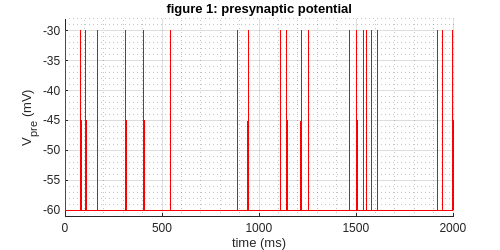

% time vector
time = 1:2000; % ms

% presynaptic membrane potential
%   spiking = -30mV
%   resting = -60mV
V_pre = -60 + 30 * (randi(100, 1, numel(time)) == 100);
I_spikes = V_pre == -30;

% Plot presynaptic potential
figure('Position', [0 0 500 250]); hold on;
plot(time, V_pre, 'r-', 'LineWidth', 1)
grid on; grid minor;
xlim([0 2000]); ylim([-61 -28])
xlabel('time (ms)'); ylabel('V_{pre} (mV)')
title('figure 1: presynaptic potential')

### Calculate `sbar & tau`

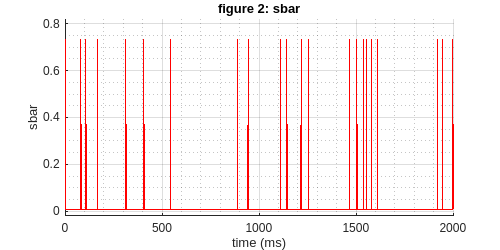

% Define functions for computing sbar and tau values
sbar   = @(V_pre) 1 ./ (1 + exp((V_th - V_pre) / delta));
tau_sg = @(V_pre) (1 - sbar(V_pre)) / k_sg;
tau_sc = @(V_pre) (1 - sbar(V_pre)) / k_sc;

% Compute sbar
sbar_  = sbar(V_pre);

% Plot the activation variable
figure('Position', [0 0 500 250]); hold on;
plot(time, sbar_, 'r-', 'LineWidth', 1)
grid on; grid minor;
xlim([0 2000]); ylim([-0.02 0.82])
xlabel('time (ms)'); ylabel('sbar')
title('figure 2: sbar')

#### Euler's Method: Compute Activation Variable, s

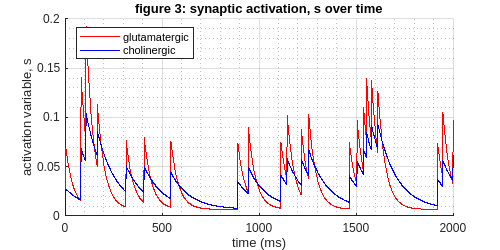

% initialize variables
dt   = 1;                     % ms - time step size
s_sg = zeros(1, numel(time)); % glutamatergic, ic: (s,t) = (0,0)
s_sc = zeros(1, numel(time)); % cholinergic, ic: (s,t) = (0,0)

% Euler's method
for i = 1:(numel(time) - 1)
    % compute derivatives
    dsdt_sg = (sbar(V_pre(i)) - s_sg(i)) / tau_sg(V_pre(i));
    dsdt_sc = (sbar(V_pre(i)) - s_sc(i)) / tau_sc(V_pre(i));

    % update variables
    s_sg(i+1) = s_sg(i) + dt * dsdt_sg;
    s_sc(i+1) = s_sc(i) + dt * dsdt_sc;
end

% Plot results
figure('Position', [0 0 500 250]); hold on;
plot(time, s_sg, 'r-', 'LineWidth', 1, 'DisplayName', 'glutamatergic')
plot(time, s_sc, 'b-', 'LineWidth', 1, 'DisplayName', 'cholinergic')
grid on; grid minor;
xlim([0 2000]); ylim([0 0.2])
xlabel('time (ms)'); ylabel('activation variable, s')
title('figure 3: synaptic activation, s over time')
legend('Location', 'northwest')

#### Compute Currents, `I_sg` and I_sc

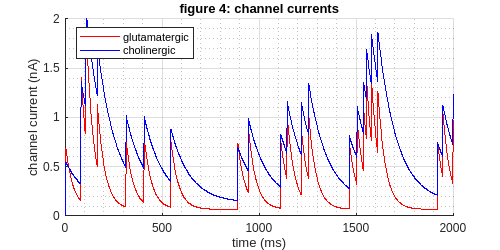

% Compute currents
I_sg = gs * s_sg * (V_post - E_sg);
I_sc = gs * s_sc * (V_post - E_sc);

% Plot currents
% Plot results
figure('Position', [0 0 500 250]); hold on;
plot(time, I_sg, 'r-', 'LineWidth', 1, 'DisplayName', 'glutamatergic')
plot(time, I_sc, 'b-', 'LineWidth', 1, 'DisplayName', 'cholinergic')
grid on; grid minor;
xlim([0 2000]); ylim([0 2])
xlabel('time (ms)'); ylabel('channel current (nA)')
title('figure 4: channel currents')
legend('Location', 'northwest')